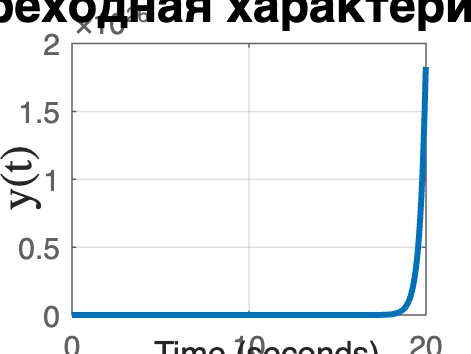

sys = tf(1.6048, [0.0640 1 0]);
A = [-2, 0, 0, 0;
    0, 3, 0 ,0;
    0, 0, 1, 3;
    0, 0, -3, 1];
B = [0;5;0;2];
C = [1,1,1,1];
D = 0;
sys = ss(A,B,C,D);
step(sys)
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;
ylabel('y(t)', 'Interpreter', 'latex', 'FontSize', 15);
title('Переходная характеристика','FontSize', 16);

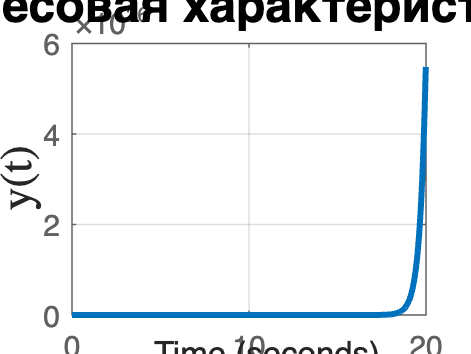


impulse(sys)
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;
ylabel('y(t)', 'Interpreter', 'latex', 'FontSize', 15);
title('Весовая характеристика','FontSize', 16);

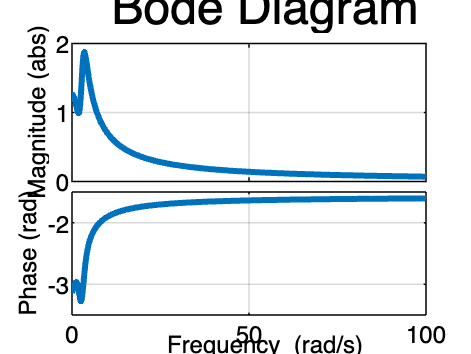


opt1 = bodeoptions;
opt1.FreqScale = 'linear';
opt1.MagScale = 'linear';
opt1.MagUnits = 'abs';
opt1.PhaseUnits = 'rad';
opt1.Title.FontSize = 16;

bodeplot(sys, opt1)
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;

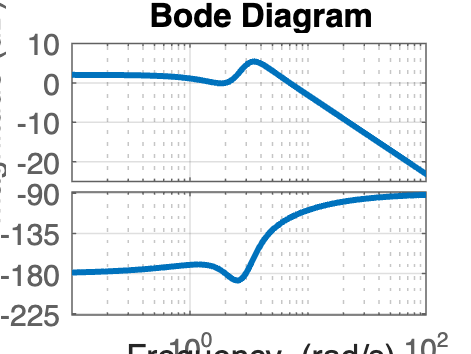


bode(sys);
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;